clc; clear all; close all;

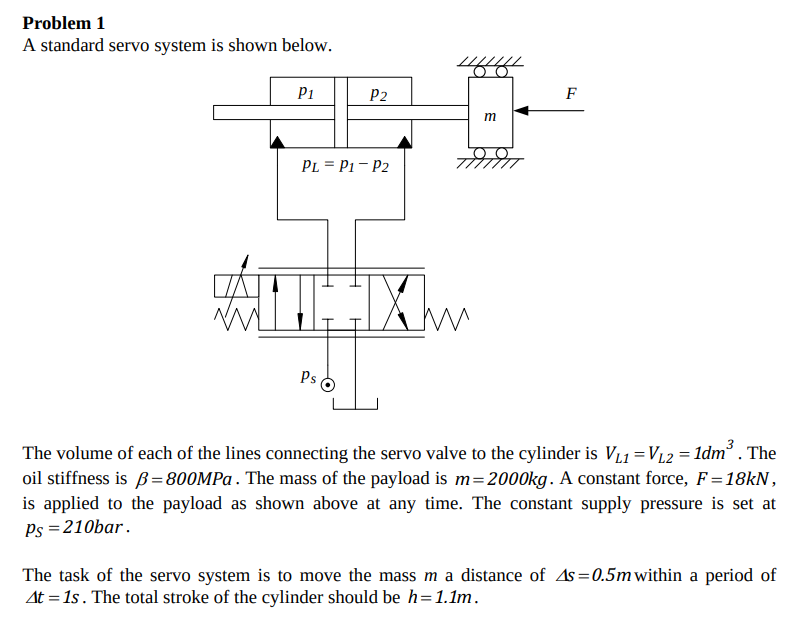

V_L1 = 10^-3; % m^3
V_L2 = V_L1; % m^3
beta = 800 * 10^6; % Pa
m = 2000; % kg
F = 18 * 10^3; % N
p_s = 210 * 10^5; % Pa
p_L = 2/3 * p_s; % p_L should be 2/3 of p_s

ds = 0.5; % m
dt = 1; % s
h = 1.1; % m

t_r = 0.2; % Ramp time, needed to calculate acceleration
dv = ds/(dt-t_r); % Average velocity
a = dv/t_r; % Acceleration, average velocity/ramp time
F_m = m * a % F = ma

F_m =         6250


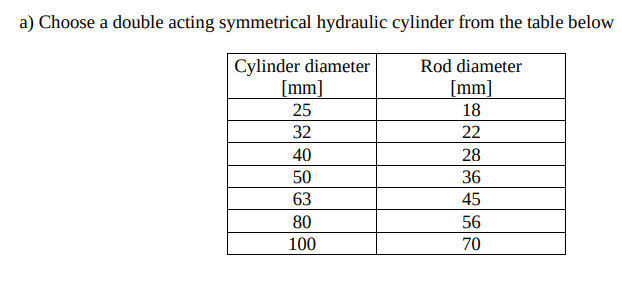

% a)
A = (F+F_m)/p_L % m^2 DONUT AREA!

A =        0.00173214285714286



cyls = [25 32 40 50 63 80 100]/1000; % Available cylinders
rods = [18 22 28 36 45 56 70]/1000;  % Available rods

A_cyls = pi./4 .* cyls.^2; % Areas of all cylinders
A_rods = pi./4 .* rods.^2; % Areas of all rods

A_donut = A_cyls - A_rods % Areas of all donut areas

A_donut =       0.000236404847182632      0.000424115008234622      0.000640884901332318      0.000945619388730528       0.00152681402964464       0.00256353960532927       0.00400553063332699



for i = 1:length(A_donut)
    if (A_donut(i) >= A) % if the donut area of area with index i is greater than or equal to the calculated area A, then the hydraulic cyl is valid
        A_donut_selected = A_donut(i) % Donut area of the selected cylinder
        selected_cyl_d = cyls(i)*1000 % cylinder diameter of the selected hydraulic cyl
        selected_rod_d = rods(i)*1000 % rod diameter of the selected hydraulic cyl
        i % index of the chosen component (referred to the table)
        break
    end
end

A_donut_selected =        0.00256353960532927


selected_cyl_d =     80


selected_rod_d =     56


i =      6


disp("Selecting cylinder with 80mm diameter, and rod with 56 diameter.")

Selecting cylinder with 80mm diameter, and rod with 56 diameter.


% b)
V_L = V_L1 + V_L2; % Slide 9, lecture 7
V_tot = h*A_donut_selected + V_L % Slide 9, lecture 7

V_tot =         0.0048198935658622



omega_n_min = 2*A_donut_selected*sqrt(beta/(m*V_tot)) % Slide 9, lecture 7

omega_n_min =           46.7069274428791


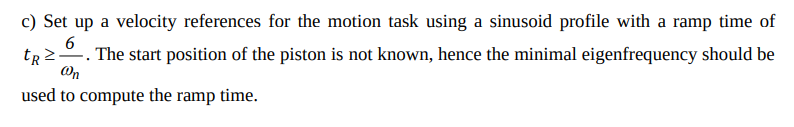

% c)
t_r_2 = 6/omega_n_min % Slide 11, lecture 7

t_r_2 =          0.128460601638543


v0 = ds/(1-t_r_2) % Calculate new vel based on new ramp time.

v0 =          0.573697529842056


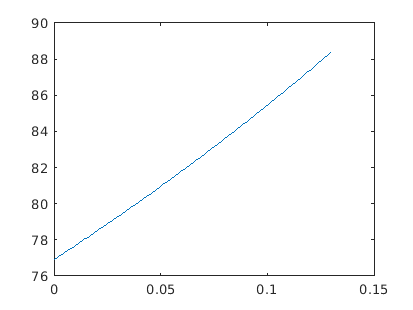

% d)
t = 0:0.001:0.13;

dv = ds./(dt-t);
a = dv./t;

Q_L = A_donut_selected*dv * 10^3 * 60;

p_L_2 = (F+m*a)./A_donut_selected;

Q_NL_max = Q_L.*sqrt(p_s./(p_s-p_L_2)) * 10^3 * 60;
plot(t,Q_L)

max(Q_NL_max)

ans =           61474178.2429513